Baudrate = 115200;
serialportlist

Undefined function or variable 'serialportlist'.

RpLidar = serialport("COM3", Baudrate, "Timeout", 1, "Parity","odd")
setDTR(RpLidar,false)







% Reset (leave protected mode)
resetStr = 'A540'
resetStrData = sscanf(resetStr, '%2x')
write(RpLidar,resetStrData,"uint8")
readReset = read(RpLidar, 5, "uint8")
dec2hex(readReset)


% Start scan
startStr = 'A521'
startStrData = sscanf(startStr, '%2x')
write(RpLidar,startStr,"uint8")
scandata = read(RpLidar, 59, "uint8")
RpLidar.NumBytesAvailable
dec2bin(scandata, 8)
dec2hex(scandata)

%flush(RpLidar, "output")


% Disconnect
clear RpLidar


stopStr = 'A525'
stopStrData = sscanf(stopStr, '%2x')
write(RpLidar,stopStr,"uint8")
readStop = read(RpLidar, 8, "uint8")
dec2hex(readStop)

% health
str = 'A552';
data = sscanf(str, '%2x');
hexStrWriteData = dec2hex(data)

write(RpLidar, data, "uint8");
readData = read(RpLidar, 10,"uint8");
hexStr = dec2hex(readData)


getInfoStr = 'A550'
getInfoStrData = sscanf(getInfoStr, '%2x')
write(RpLidar,getInfoStrData,"uint8")
readInfo = read(RpLidar, 20,"uint8")
hexStr = dec2hex(readInfo)


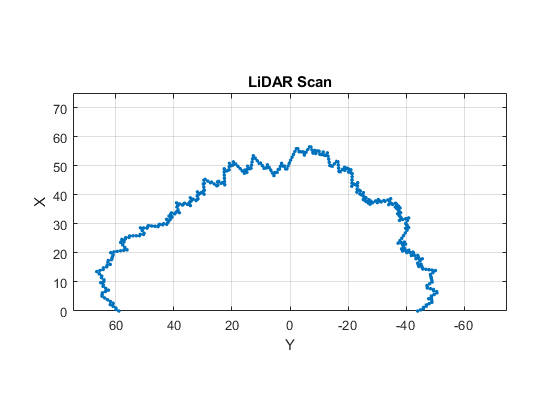

start = randi([40, 50],1,1);
ranges = zeros(1, 360);
ranges(1) = start;

for i = 2:360
    rand_add = randi([-1, 1], 1, 1);
    ranges(i) = ranges(i-1) + rand_add;
    
end
ranges;


angles = linspace(-pi/2, pi/2, numel(ranges));
scan = lidarScan(ranges, angles);
plot(scan)

## connect to bluetooth device

bluetoothlist

Run blelist to search for nearby Bluetooth Low Energy peripheral devices.


ans = 5×4 table
                Name                   Address        Channel          Status      
    ____________________________    ______________    _______    __________________

    "MOMENTUM M2 AEBT"              "001B668B8130"    Unknown    "Unknown"         
    "MOMENTUM 3"                    "001B66CDE2EF"    Unknown    "Unknown"         
    "[TV] Samsung 7 Series (65)"    "D003DFE3F853"    Unknown    "Unsupported"     
    "raspberrypi"                   "B827EB5F2624"    1          "Requires pairing"
    "Galaxy Watch (D631)"           "DCF756CE3631"    Unknown    "

blelist

Run bluetoothlist to search for nearby Bluetooth classic devices.


ans = 9×5 table
    Index         Name            Address        RSSI    Advertisement
    _____    ______________    ______________    ____    _____________

      1      ""                "78CE74B9D340"    -76     [1×1 struct] 
      2      ""                "230A281B3BF4"    -79     [1×1 struct] 
      3      ""                "401323F6217A"    -81     [1×1 struct] 
      4      ""                "6E367DD80D36"    -82     [1×1 struct] 
      5      ""                "62786CBAA3AA"    -83     [1×1 struct] 
      6      ""                "6E0A7A7B86A1"    -84     [1×1 struct] 
      7      "ONE R EQ58BD"    "102C6B50ECB3"    -89     [1×1 struct] 
      8      ""                "6F7E5CCCCF62"    -89     [1×1 struct] 
      9      ""                "08EF3B6DD1A3"    -91     [1×1 struct] 



device = bluetooth("raspberrypi", 1)

device =   bluetooth with properties:

                 Name: "raspberrypi"
              Address: "B827EB5F2624"
              Channel: 1
    NumBytesAvailable: 0
      NumBytesWritten: 0

  Show all properties


clear device

testSrt = 'A'

testSrt = 'A'

write(device, testSrt,"int8")

pause(3)

stopStr = 'B'

stopStr = 'B'

write(device, stopStr,"int8")


stopStr = 'B'

stopStr = 'B'

write(device, stopStr,"int8")

backStr = 'C'

backStr = 'C'

write(device, backStr,"int8")

pause(3)

backStoppStr = 'D'

backStoppStr = 'D'

write(device, backStoppStr,"int8")

backStoppStr = 'D'

backStoppStr = 'D'

write(device, backStoppStr,"int8")

## Plot with psuedo randomly generated values

% Generate enviroment
start = randi([15, 20],1,1);
ranges = zeros(1, 360);
ranges(1) = start;

for i = 2:360
    rand_add = randi([-1, 1], 1, 1);
    ranges(i) = ranges(i-1) + rand_add;
    
end

theta = linspace(0, 360, 360);
%rho = randi([0, 10], 360, 1);
theta_rad = deg2rad(theta);
polarplot(theta_rad, ranges, '.')
hold on


% obstacle detection
detection_range = 15

detection_range = 15

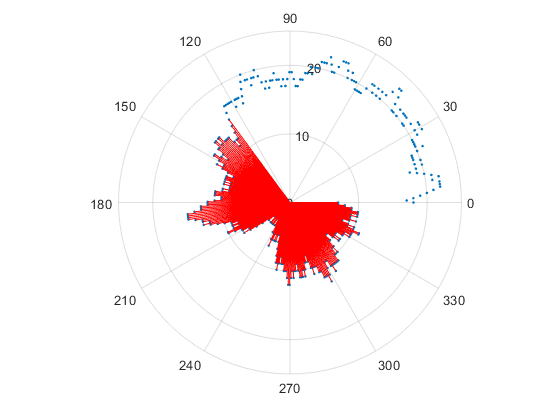

collision_vector = obstDet(detection_range, theta_rad, ranges);
hold off




% Avoid obstacle
direction = 1; % 1 = forward, 2 = backward, 3 = right, 4 = left
obstAvoid(direction, collision_vector)

F


ans = 2

## Shape 1 Square without obstacle

% Generate cartesian square
[x_square, y_square] = genCatSq(20);


% generate polar cordinates
[theta_square, rho_square] = cart2pol(x_square, y_square);

%plot figure
figure
polarplot(theta_square, rho_square, '.')
hold on


% obstacle detection
detection_range = 15

detection_range = 15

collision_vector = obstDet(detection_range, theta_square, rho_square);

% obstacle avoidance
direction = 1;
obstAvoid(direction, collision_vector)

F


ans = 2

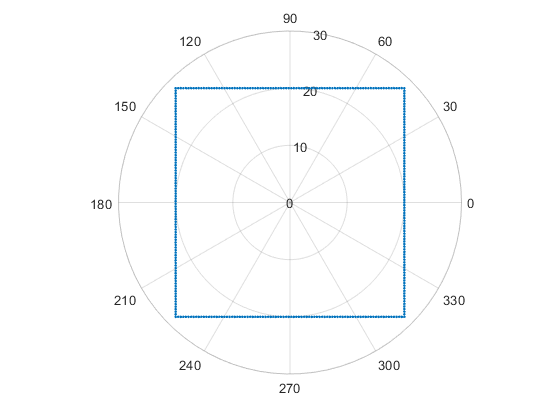


hold off

## Shape 2 Square with obstacle

% Generate cartesian square
[x_square, y_square] = genCatSq(20);


% generate polar cordinates
[theta_square, rho_square] = cart2pol(x_square, y_square);


theta_square_obst = theta_square;
rho_square_obst = rho_square;

rho_square_obst(22:170) = 15;
rho_square_obst(120:150) = 13;

% Plot square
figure
% kan rimligtvis bytas ut mot polarscatter
polarplot(theta_square_obst, rho_square_obst, '.')
hold on

% Detection
detection_range = 13

detection_range = 13

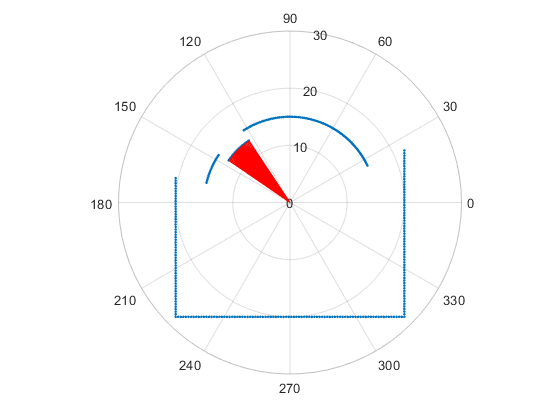

collision_vector = obstDet(detection_range, theta_square_obst, rho_square_obst);
hold off


% Avoid obstacle
direction = 1; % 1 = forward, 2 = backward, 3 = right, 4 = left
obstAvoid(direction, collision_vector)

F


ans = 2

## Generate cartesian square with 360 dots function

function [x_square, y_square] = genCatSq(size)
x_v1 = ones(1,45) * size;
x_v2 = linspace(size, -size, 90);
x_v3 = ones(1, 90) * (-size);
x_v4 = linspace(-size, size, 90);
x_v5 = ones(1,45) * size;
x_square = [x_v1 x_v2 x_v3 x_v4 x_v5];

y_v1 = linspace(0, size, 45);
y_v2 = ones(1,90) * size;
y_v3 = linspace(size, -size, 90);
y_v4 = ones(1,90) * (-size);
y_v5 = linspace(-size, 0, 45);
y_square = [y_v1 y_v2 y_v3 y_v4 y_v5];
end

## Obstacle Detection function

function d = obstDet(range, theta, rho)
d = zeros(1,360);
for i = 1:360
    if  abs(rho(i)) <= range
        line_angle = [theta(i) theta(i)];
        line_range = [0 rho(i)];
        polarplot(line_angle, line_range, 'r')
        d(i) = 1;
    end
end

end

## Obstacle Avoidance function

function u = obstAvoid(direction, collision_vector)

collision_angles = find(collision_vector == 1);
number_of_collisions = size(collision_angles);

Zone_A = true;  % 337.5 - 22.5
Zone_B = true;  % 22.5 - 67.5
Zone_C = true;  % 67.5 - 112.5
Zone_D = true;  % 112.5 - 157.5
Zone_E = true;  % 157.5 - 202.5
Zone_F = true;  % 202.5 - 247.5
Zone_G = true;  % 247.5 - 292.5
Zone_H = true;  % 292.5 - 337.5



for i = 1:number_of_collisions(1,2)
    if (collision_angles(i) <= 22.5) || (collision_angles(i) >= 337.5)
        Zone_A = false;
    
    elseif (collision_angles(i) <= 67.5) && (collision_angles(i) >= 22.5)
        Zone_B = false;
        
    elseif (collision_angles(i) <= 112.5) && (collision_angles(i) >= 67.5)
        Zone_C = false;
        
    elseif (collision_angles(i) <= 157.5) && (collision_angles(i) >= 112.5)
        Zone_D = false;
        
    elseif (collision_angles(i) <= 202.5) && (collision_angles(i) >= 157.5)
        Zone_E = false;
        
    elseif (collision_angles(i) <= 247.5) && (collision_angles(i) >= 202.5)
        Zone_F = false;
        
    elseif (collision_angles(i) <= 292.5) && (collision_angles(i) >= 247.5)
        Zone_G = false;
        
    elseif (collision_angles(i) <= 337.5) && (collision_angles(i) >= 292.5)
        Zone_H = false;
        
    end
    
end



if direction == 1

    if Zone_C == true
        disp("F")
        u = 2;
        
    elseif (Zone_B == false) || (Zone_A == false)
        if Zone_D == true
            disp("FL")
            u = 3;
        elseif (Zone_D == false) && (Zone_E == true)
            disp("L")
            u = 4;
        elseif Zone_B == true
            disp ("FR")
            u = 1;
        elseif Zone_A == true
            disp ("R")
            u = 0;
        else 
            disp("Error 001")
            u = 8;
            
        end
        
    elseif (Zone_D == false) || (Zone_E == false)
        if Zone_B == true
            disp("FR")
            u = 1;
        elseif (Zone_B == false) && (Zone_A == true)
            disp("R")
            u = 0;
        elseif Zone_D == true
            disp ("FL")
            u = 3;
        elseif Zone_E == true
            disp ("L")
            u = 4;
        else
            disp("Error 002")
            u = 9;
        end
    end
    
    
elseif direction == 2
    
    if Zone_G == true
        disp("B")
        u = 6;
        
    elseif (Zone_H == false) || (Zone_A == false)
        if Zone_F == true
            disp("BL")
            u = 5;
        elseif (Zone_F == false) && (Zone_E == true)
            disp("L")
            u = 4;
        elseif Zone_H == true
            disp ("BR")
            u = 7;
        elseif Zone_A == true
            disp ("R")
            u = 0;
        else
            disp("Error 003")
            u = 10;
        end
        
    elseif (Zone_E == false) || (Zone_F == false)
        if Zone_H == true
            disp("BR")
            u = 7;
        elseif (Zone_H == false) && (Zone_A == true)
            disp("R")
            u = 0;
        elseif Zone_F == true
            disp ("BL")
            u = 5;
        elseif Zone_E == true
            disp ("L")
            u = 4;
        else
            disp("Error 004")
            u = 11;
        end
    end
    
    
elseif direction == 3
    
    if Zone_A == true
        disp("R")
        u = 0;
        
    elseif (Zone_G == false) || (Zone_H == false)
        if Zone_B == true
            disp("FR")
            u = 1;
        elseif (Zone_B == false) && (Zone_C == true)
            disp("F")
            u = 2;
        elseif Zone_H == true
            disp ("BR")
            u = 7;
        elseif Zone_G == true
            disp ("B")
            u = 6;
        else
            disp("Error 005")
            u = 12;
        end
        
    elseif (Zone_C == false) || (Zone_B == false)
        if Zone_H == true
            disp("BR")
            u = 7;
        elseif (Zone_H == false) && (Zone_G == true)
            disp("B")
            u = 6;
        elseif Zone_B == true
            disp ("FR")
            u = 1;
        elseif Zone_C == true
            disp ("F")
            u = 2;
        else
            disp("Error 006")
            u = 13;
        end
    end
    
    
    
elseif direction == 4
    
    if Zone_E == true
        disp("L")
        u = 4;
        
    elseif (Zone_F == false) || (Zone_G == false)
        if Zone_D == true
            disp("FL")
            u = 3;
        elseif (Zone_D == false) && (Zone_C == true)
            disp("F")
            u = 2;
        elseif Zone_F == true
            disp ("BL")
            u = 5;
        elseif Zone_G == true
            disp ("B")
            u = 6;
        else
            disp("Error 007")
            u = 14;
        end
        
    elseif (Zone_D == false) || (Zone_C == false)
        if Zone_F == true
            disp("BL")
            u = 5;
        elseif (Zone_F == false) && (Zone_G == true)
            disp("B")
            u = 6;
        elseif Zone_D == true
            disp ("FL")
            u = 3;
        elseif Zone_C == true
            disp ("F")
            u = 2;
        else
            disp("Error 008")
            u = 15;
        end
    end
    
end

end


